clear all
close all
info = readtable('INFO.csv')

info = 2×2 table
      Information       Value
    ________________    _____

    {'Frame Width' }    1280 
    {'Frame Height'}     720 


x_coo = readtable('x_coordinates.csv'); 
y_coo = readtable('y_coordinates.csv');
bb = size(x_coo); number_boxes = bb(2);

for c = 2:number_boxes
    y_coo{:,c} = (info.Value(2) - y_coo{:,c}); 
end


## TRAJECTORIES PLOT

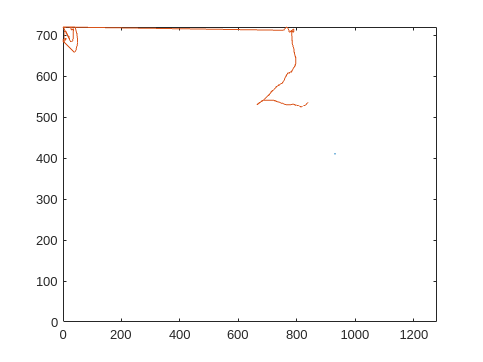

figure(1)
y = randi(10,10,1);
plot(x_coo.Box1,y_coo.Box1); hold on;
plot(x_coo.Box2,y_coo.Box2); hold off

% for box = 1:number_boxes
%     BOX = sprintf("Box%d",box);
% 
%     plot(x_coo.BOX,y_coo.Box1,'color',y(box)); hold on;
%     plot(x_coo.BOX,y_coo.Box2,'color',y(box)'); hold on
% end

axis([0 info.Value(1) 0 info.Value(2)])


    x_coo_array = table2array(x_coo);
    y_coo_array = table2array(y_coo);

## DELETE STATIC BOXES

v_fail = [];
traj_all_x = []; traj_all_y =[];
for b = 2:number_boxes
    traj_x = zeros(1,length(x_coo_array));
    traj_y = zeros(1,length(x_coo_array));

    x_q = x_coo_array(:,b);
    y_q = y_coo_array(:,b);

    for ii = 1:length(x_coo_array)-1  
        if x_q(ii+1)-x_q(ii) > 10 || y_q(ii+1)-y_q(ii) > 10
            fail = x_coo_array(ii,1);
            v_fail = [v_fail; fail];
        end

    end
    
    for t = 1:length(v_fail)
        if t == 1
            traj_x = [x_q(1:v_fail(1)), zeros(1,length(traj_x)-length(x_q(1:v_fail(1))))];

            traj_y = [y_q(1:v_fail(1)), zeros(1,length(traj_y)-length(y_q(1:v_fail(1))))];

        else
            traj_x = [x_q(v_fail(t-1)+1:v_fail(t)), zeros(1,length(traj_x)-length(x_q(v_fail(t-1)-1:v_fail(t))))];

            traj_y = [y_q(v_fail(t-1)+1:v_fail(t)), zeros(1,length(traj_y)-length(y_q(v_fail(t-1)-1:v_fail(t))))];

        end

        traj_all_x = [traj_all_x; traj_x];
        traj_all_y = [traj_all_y; traj_y];

    end

end

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


figure(2)
for mm = 1:length(traj_all_y)
    plot(traj_all_x(mm,:),traj_all_y(mm,:)); hold on
end








